**Question 1:** The orientation of a spacecraft B relative to an inertial frame is given through the 3-2-1 Euler angle sequence, with initial conditions: θB = [10 − 15 30]T degrees The attitude control system makes the spacecraft rotate with angular velocity ω Bi = [1 1 1]T rad/s expressed in FB. Integrate the quaternion equations of motion to obtain q¯(t), for t = 0 to 20 seconds. Make a presentation-quality plot of the elements of q¯(t) over the given time range.

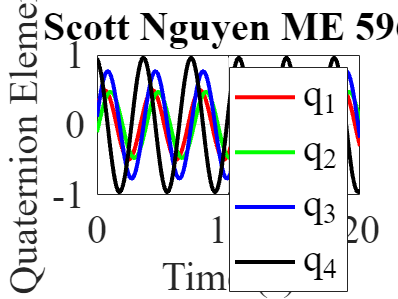

clear
clc

ang = deg2rad([10; -15; 30]);
w_i = [1; 1; 1];

R = rot_1(ang(3)) * rot_2(ang(2)) * rot_3(ang(1));

q_0 = rot_to_quat(R);

qdot = @(t, q) qdot_func(t, q, w_i);

tspan = [0 20];

[t, q] = ode45(@(t, q) qdot(t, q), tspan, q_0);

figure;
plot(t, q(:,1), 'r', 'LineWidth', 2);
hold on;
plot(t, q(:,2), 'g', 'LineWidth', 2);
plot(t, q(:,3), 'b', 'LineWidth', 2);
plot(t, q(:,4), 'k', 'LineWidth', 2);
hold off;

fontSize = 20;
set(gca, 'FontName', 'Times New Roman', 'FontSize', fontSize);
xlabel('Time (s)', 'FontName', 'Times New Roman', 'FontSize', fontSize);
ylabel('Quaternion Elements', 'FontName', 'Times New Roman', 'FontSize', fontSize);
legend('q_1', 'q_2', 'q_3', 'q_4', 'FontName', 'Times New Roman', 'FontSize', fontSize);
title('Scott Nguyen ME 596', 'FontName', 'Times New Roman', 'FontSize', fontSize);
grid on;

**Question 2:** Two pairs of photocells are arranged in a perpendicular configuration, and measure sun direction angles of α1 = 45◦ and α2 = 60◦ . Calculate the components of the unit sun vector in sun sensor frame, Fs = � nˆ1, nˆ2, ˆt . The sensor frame Fs is oriented in the spacecraft body frame, Fb, by Rsb, which is a 3-2-1 Euler angle rotation sequence through the angles θ1 = 45◦ , θ2 = 180◦ , and θ3 = 90◦ from Fb to Fs. Calculate the components of the unit sun vector in Fb. The spacecraft generates power using a single solar panel. The components of the unit normal vector of the panel expressed in Fb are pb = (0 − 1 0)T . The panel generates the maximum amount of power when it is perpendicular to the incoming sunlight, so we want to know the angle between the sun vector and the unit normal vector of the panel. Calculate the angle between ˆs and pˆ.

clear
clc

alpha = deg2rad([45; 60]);

s_star = [1; 
          tan(alpha(1)) / tan(alpha(2)); 
          tan(alpha(1))];

s_s = s_star / norm(s_star);

ang = deg2rad([45; 180; 90]);

R_sb = rot_1(ang(3)) * rot_2(ang(2)) * rot_3(ang(1));

s_b = R_sb' * s_s;

p_b = [0; -1; 0];

ang = acos(dot(s_b, p_b) / (norm(s_b) * norm(p_b)));

fprintf('Problem 2\n\n');

Problem 2




fprintf('Sun vector in the sun sensor frame (s_s):\n');

Sun vector in the sun sensor frame (s_s):


fprintf('%.4f\n', s_s);

0.6547
0.3780
0.6547



fprintf('R^{sb}:\n');

R^{sb}:


disp(R_sb);

   -0.7071   -0.7071   -0.0000
    0.0000    0.0000   -1.0000
    0.7071   -0.7071   -0.0000




fprintf('R^{bs}:\n');

R^{bs}:


disp(R_sb');

   -0.7071    0.0000    0.7071
   -0.7071    0.0000   -0.7071
   -0.0000   -1.0000   -0.0000




fprintf('\nSun vector in the spacecraft body frame (s_b):\n');


Sun vector in the spacecraft body frame (s_b):


fprintf('%.4f\n', s_b);

-0.0000
-0.9258
-0.3780



fprintf('\nAngle between the sun vector (s_b) and the panel normal (p_b):\n');


Angle between the sun vector (s_b) and the panel normal (p_b):


fprintf('%.4f degrees\n', rad2deg(ang));

22.2077 degrees


**Question 3:** Consider two unit vectors vˆ1 and vˆ2. (These vectors could be sun vector, magnetic field vector, Earth horizon vector, or any other vector for which a model and a sensor are available.) The components of vˆ1 and vˆ2 expressed relative to the inertial frame are known to be 

v1i = 0.6651 0.7395 0.1037 � T 

v2i = 0.8190 0.5670 0.0875 � T 

Sensors on a spacecraft measure the components of vˆ1 and vˆ2 relative to the body frame to be 

v1b = 0.5629 −0.3243 −0.7592 � T 

v2b = 0.5770 −0.5186 −0.6299 � T 

Use the TRIAD algorithm with vˆ1 as the “exact” measurement and determine the rotation matrix R bi. Repeat using vˆ2 as the “exact” measurement. 

If the “true” rotation matrix R bi is given by a 3-2-1 Euler angle rotation sequence through the angles θ1 = 30◦ , θ2 = −60◦ , and θ3 = 45◦ , calculate the attitude error for each case of applying TRIAD. Express your answer as a principal Euler angle; i.e., calculate the Euler angle of the rotation matrix relating the estimated Fb and the true Fb.

 Using your calculated errors, which sensor do you think is more accurate (the one that provides v1b or the one that provides v2b)? Justify your reasoni

clear
clc

v_1b = [0.5629; -0.3243; -0.7592];
v_2b = [0.5770; -0.5186; -0.6299];

v_1i = [0.6651; 0.7395; 0.1037];
v_2i = [0.8190; 0.5670; 0.0875];

ang = deg2rad([30; -60; 45]);
R_bi = rot_1(ang(3)) * rot_2(ang(2)) * rot_3(ang(1));

v_b = [v_1b, v_2b];
v_i = [v_1i, v_2i];

[R_bi_1, J_1] = triad(v_b, v_i, 1);
[R_bi_2, J_2] = triad(v_b, v_i, 2);

[phi_e1, ~] = rot_to_eul(R_bi * R_bi_1');
[phi_e2, ~] = rot_to_eul(R_bi * R_bi_2');

fprintf('\nTrue Rotation Matrix R_bi:\n')


True Rotation Matrix R_bi:


disp(R_bi)

    0.4330    0.2500    0.8660
   -0.8839    0.3062    0.3536
   -0.1768   -0.9186    0.3536



fprintf('\nResults for Truth Vector v_1:\n')


Results for Truth Vector v_1:


fprintf('Rotation Matrix (R_bi_1):\n')

Rotation Matrix (R_bi_1):


disp(R_bi_1)

    0.4480    0.2374    0.8616
   -0.8772    0.2979    0.3745
   -0.1678   -0.9237    0.3425



fprintf('Euler Angles Error:\n')

Euler Angles Error:


disp(rad2deg(phi_e1))

    2.6929



fprintf('Wahba Cost:\n')

Wahba Cost:


disp(J_1)

   5.1102e-06




fprintf('\nResults for Truth Vector v_2:\n')


Results for Truth Vector v_2:


fprintf('Rotation Matrix (R_bi_2):\n')

Rotation Matrix (R_bi_2):


disp(R_bi_2)

    0.4473    0.2385    0.8617
   -0.8781    0.2960    0.3743
   -0.1658   -0.9242    0.3425



fprintf('Euler Angles Error:\n')

Euler Angles Error:


disp(rad2deg(phi_e2))

    2.5893



fprintf('Wahba Cost:\n')

Wahba Cost:


disp(J_2)

   5.0892e-06



**Question 4:** Repeat Problem 3 using the q-Method to determine the rotation matrix R bi. Assume that the two measurements are equally weighted, w1 = w2 = 1. 

Calculate the attitude error as a principal Euler angle, and compare the error determined in this problem to the errors calculated in Problem 3. 

Calculate the value of Wahba’s loss function J(Rbi) and compare the value determined in this problem to the values for the rotation matrices calculated in Problem

clear
clc

v_1b = [0.5629; -0.3243; -0.7592];
v_2b = [0.5770; -0.5186; -0.6299];

v_1i = [0.6651; 0.7395; 0.1037];
v_2i = [0.8190; 0.5670; 0.0875];

ang = deg2rad([30; -60; 45]);

R_bi = rot_1(ang(3)) * rot_2(ang(2)) * rot_3(ang(1));

v_b = [v_1b, v_2b];

v_i = [v_1i, v_2i];
w_k = [1; 1];
[q, R_bi_q, J_q] = q_method(v_b, v_i, w_k);
[phi_q, ~] = rot_to_eul(R_bi' * R_bi_q);

fprintf('q-method Results:\n')

q-method Results:


disp('Quaternion (q):')

Quaternion (q):


disp(q)

    0.4495
   -0.3560
    0.3864
    0.7224



disp('Rotation matrix (R_bi_q):')

Rotation matrix (R_bi_q):


disp(R_bi_q)

    0.4480    0.2382    0.8617
   -0.8783    0.2972    0.3744
   -0.1669   -0.9246    0.3424



disp('Euler angles (phi_q) in degrees:')

Euler angles (phi_q) in degrees:


disp(rad2deg(phi_q)) 

    1.3953



disp('Cost function (J_q):')

Cost function (J_q):


disp(J_q)

   3.5452e-06



**Question 5:** Repeat Problem 3 using the QUEST algorithm to determine the rotation matrix R bi . Assume that the two measurements are equally weighted, w1 = w2 = 1.

clear
clc

v_1b = [0.5629; -0.3243; -0.7592];
v_2b = [0.5770; -0.5186; -0.6299];

v_1i = [0.6651; 0.7395; 0.1037];
v_2i = [0.8190; 0.5670; 0.0875];

ang = deg2rad([30; -60; 45]);
R_bi = rot_1(ang(3)) * rot_2(ang(2)) * rot_3(ang(1));

v_b = [v_1b, v_2b];
v_i = [v_1i, v_2i];

w_k = [1; 1];

[q, R_bi_QUEST, J_QUEST] = quest(v_b, v_i, w_k);

[phi_q, ~] = rot_to_eul(R_bi' * R_bi_QUEST);

fprintf('QUEST Algorithm Results:\n');

QUEST Algorithm Results:


fprintf('Rotation Matrix (R_bi_QUEST):\n');

Rotation Matrix (R_bi_QUEST):


disp(R_bi_QUEST);

    0.4427    0.2447    0.8626
   -0.8803    0.3015    0.3663
   -0.1705   -0.9215    0.3489



fprintf('Euler Angles (phi_q) in degrees:\n');

Euler Angles (phi_q) in degrees:


disp(rad2deg(phi_q));

    0.8099



fprintf('Cost Function Value (J_QUEST):\n');

Cost Function Value (J_QUEST):


disp(J_QUEST);

   7.6177e-06

